clear ;
close all;

tic
load ryan3_data.mat
toc 

Elapsed time is 1.351235 seconds.


generate_model = true

generate_model = logical
   1


if generate_model == false
    load ryan3_model_Vd_SOH.mat
end

%generate_model = false
% https://kr.mathworks.com/help/matlab/ref/load.html
%load('ryan3_gen_data.mat','battery_dataset')


# 선형회귀 모델 생성

if generate_model
    
tic
mdl_Vd_SOH = fitlm(x_trainValid_Vd_SOH,y_trainValid_SOH)
toc

ryan3_model_Vd_SOH_desc = 'ryan3_model_Vd_SOH_desc';
save('ryan3_model_Vd_SOH.mat','ryan3_model_Vd_SOH_desc')
save('ryan3_model_Vd_SOH.mat','mdl_Vd_SOH')

end

mdl_Vd_SOH = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate       SE         tStat        pValue   
                   ________    _________    ________    ___________

    (Intercept)      10.239     0.088837      115.25              0
    x1             -0.10856    0.0049403     -21.974    2.3179e-106
    x2               -22.24       1.0035     -22.163    3.7201e-108
    x3               48.594       2.4353      19.954     3.8751e-88
    x4              -32.415       2.5192     -12.867     8.2431e-38
    x5              -4.4517       2.3201     -1.9188       0.055019
    x6          

Elapsed time is 0.315964 seconds.


# 선형회귀 예측

coeff = mdl_Vd_SOH.Coefficients.Estimate

coeff =    10.2386
   -0.1086
  -22.2405
   48.5941
  -32.4147
   -4.4517
  -26.9626
    5.6155
   -2.0151
   17.8124


x_trainValid_Vd_SOH(1,:)

ans =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid_Vd_SOH*coeff(2:21)+coeff(1)

yhat =     1.0262
    1.0300
    1.0195
    1.0233
    1.0256
    1.0265
    1.0241
    1.0268
    1.0216
    1.0205


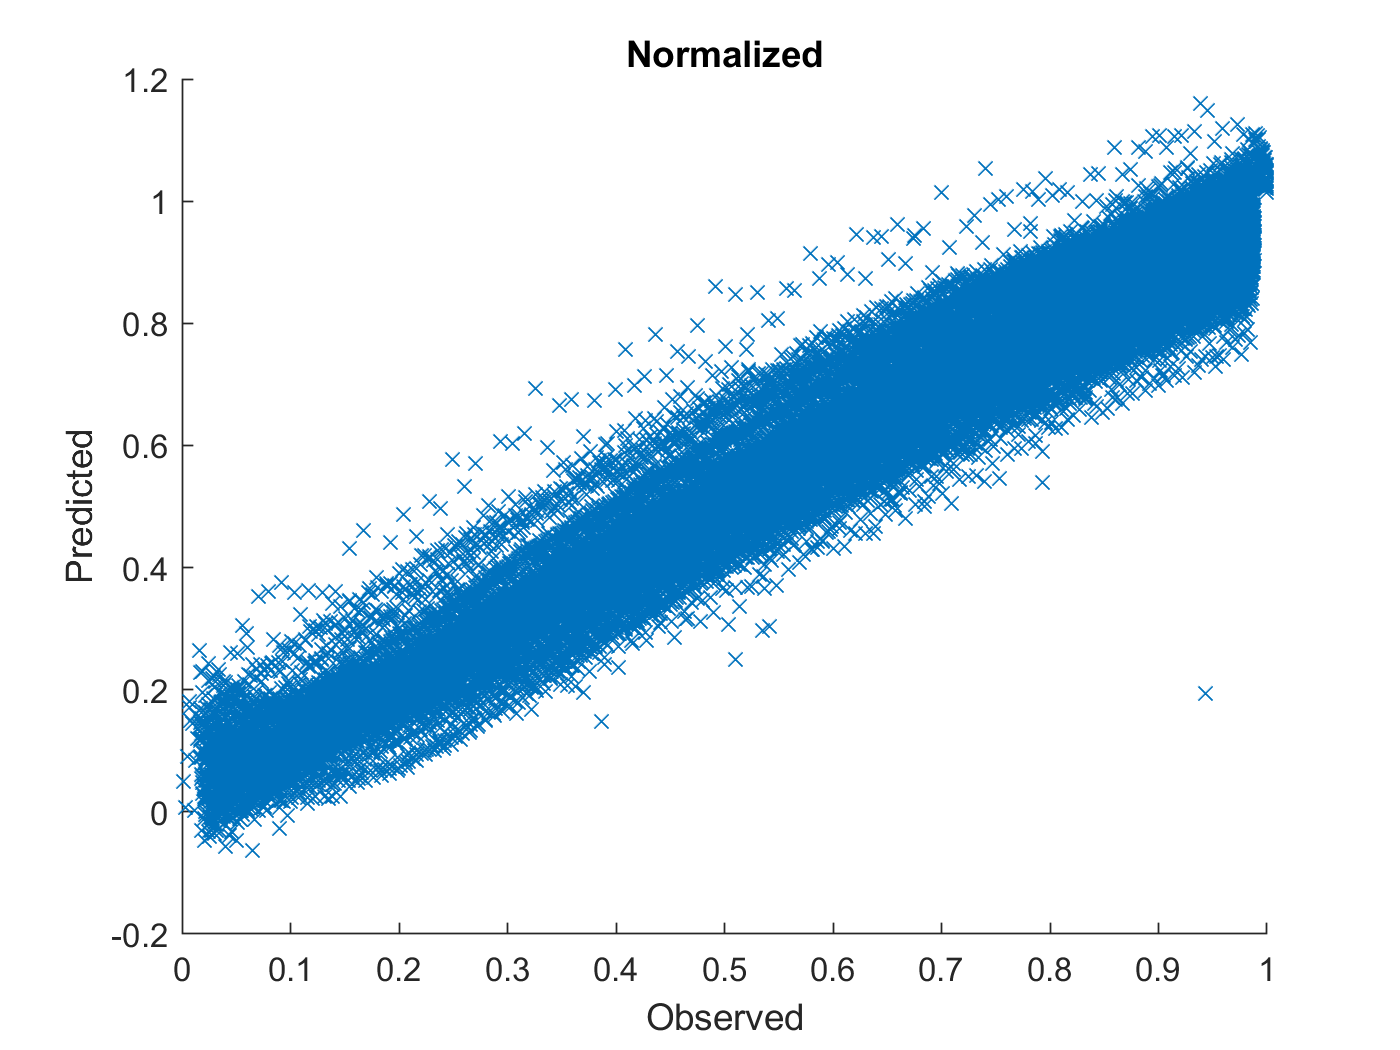

figure
hold on
plot(y_trainValid_SOH,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

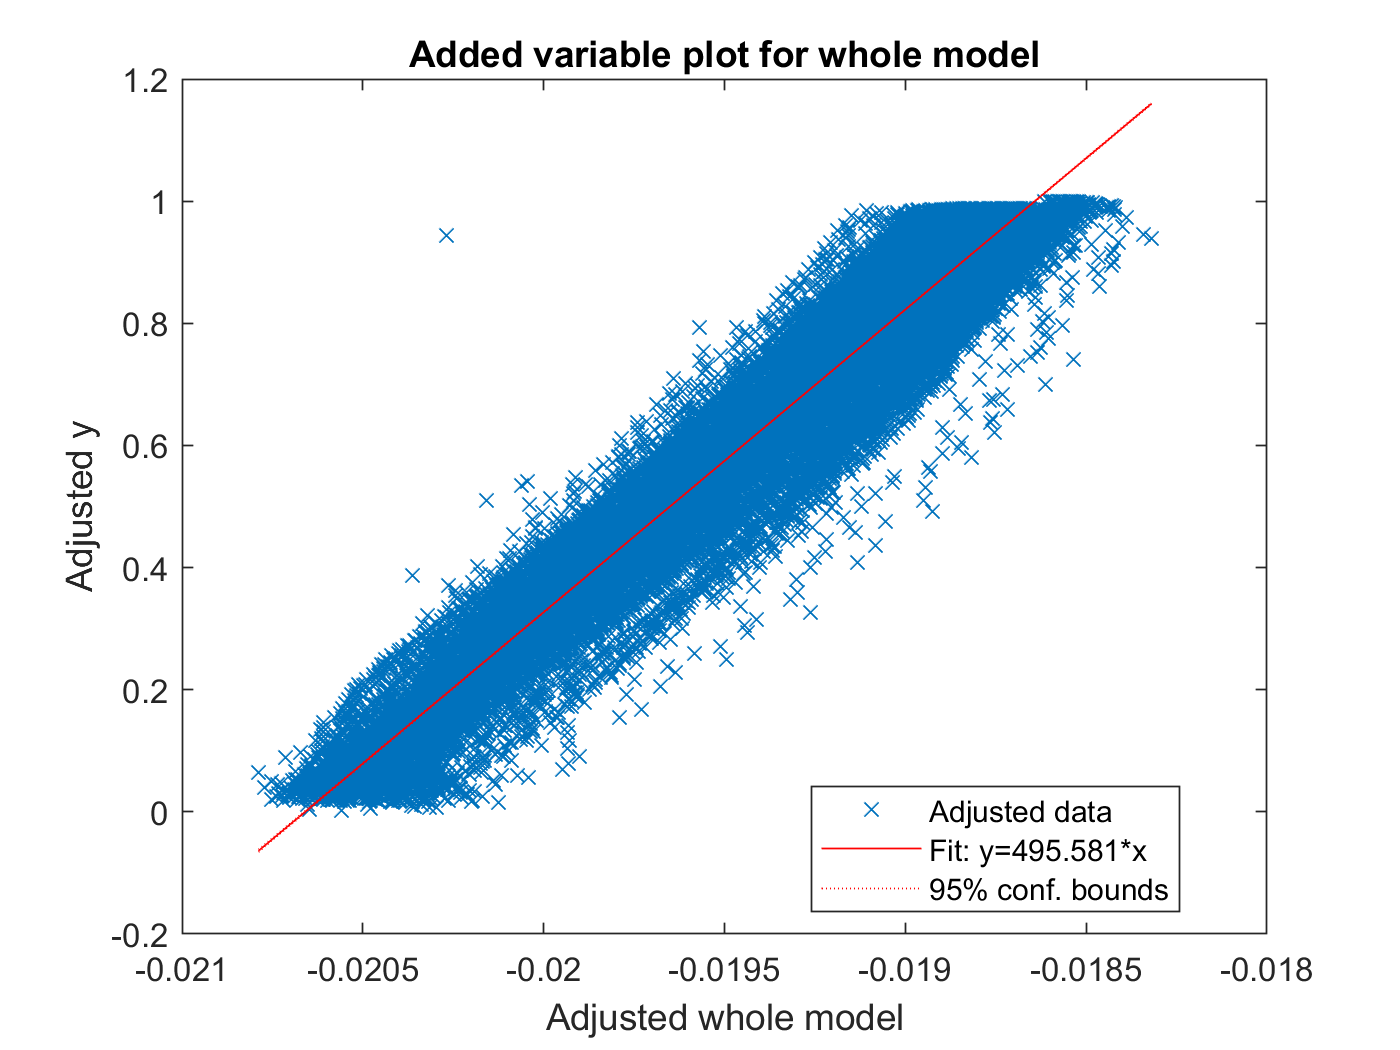


%capHat = Ic(1)

plot(mdl_Vd_SOH)

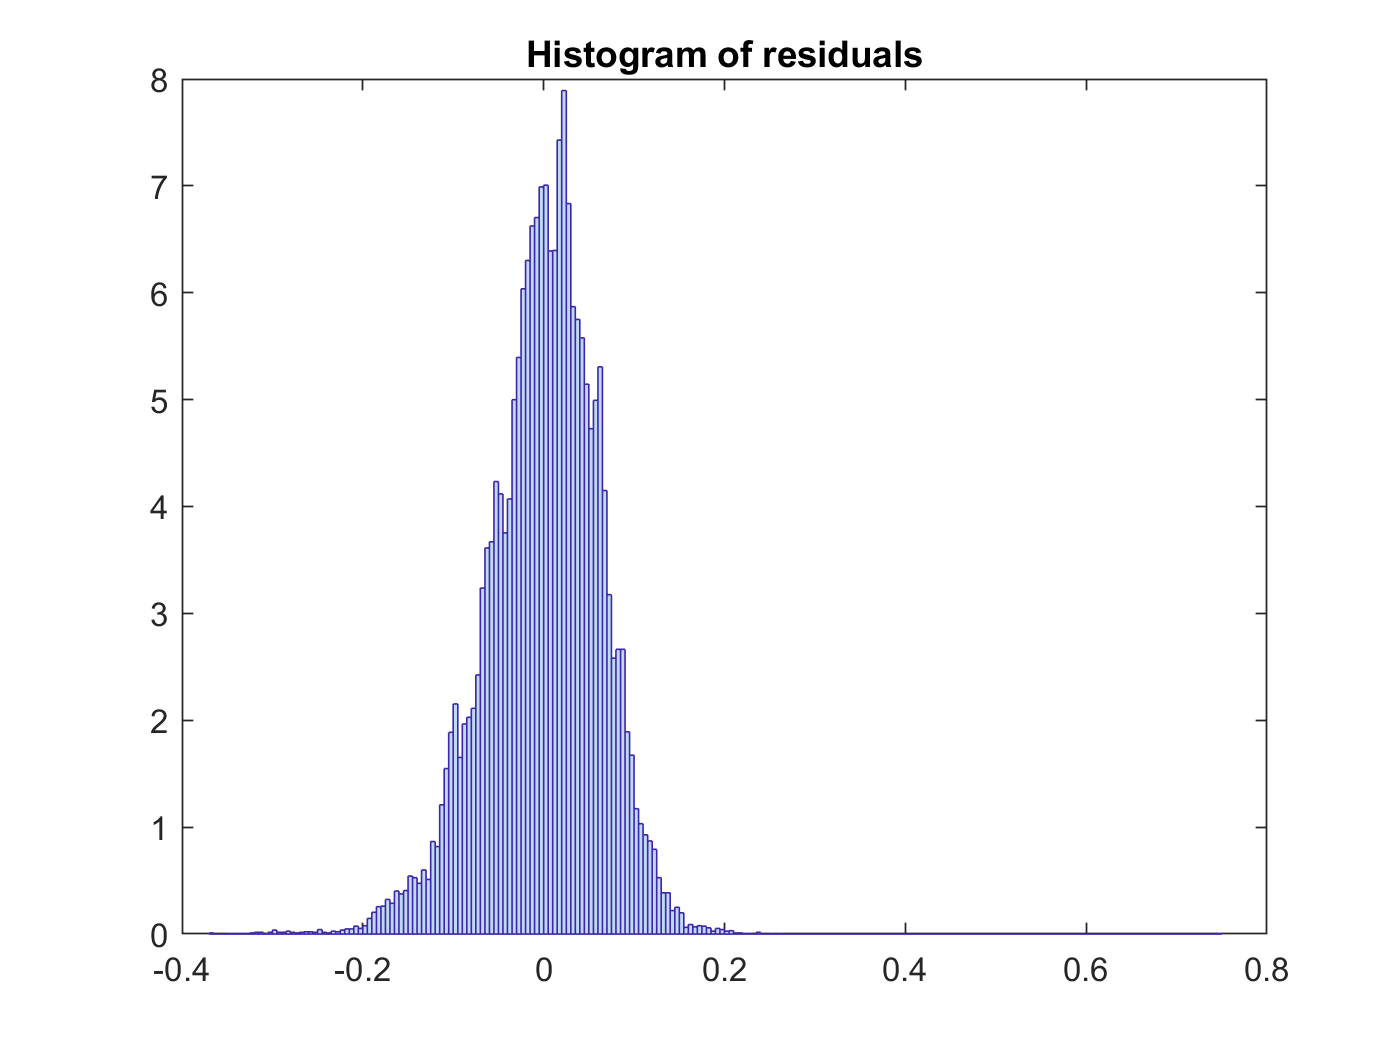

plotResiduals(mdl_Vd_SOH)




% yfit = predict(mdl_Vd_SOH,Ic)
yfit = predict(mdl_Vd_SOH,x_trainValid_Vd_SOH)

yfit =     1.0262
    1.0300
    1.0195
    1.0233
    1.0256
    1.0265
    1.0241
    1.0268
    1.0216
    1.0205


yfit_test = predict(mdl_Vd_SOH,x_test_Vd_SOH)

yfit_test =     0.9468
    0.9518
    0.9539
    0.9475
    0.9437
    0.9481
    0.9468
    0.9494
    0.9460
    0.9497




y= y_trainValid_SOH

y =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test_SOH

y_test_SOH =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


# denormaize

yfit = yfit * yrate_SOH + ymin_SOH;
y = y * yrate_SOH + ymin_SOH;
yfit_test = yfit_test * yrate_SOH + ymin_SOH;

MAE = mean(abs(yfit-y))

MAE = 0.0084

adjMAE = MAE/range(y)

adjMAE = 0.0483

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(y - yhat)    % Errors

ans =     0.0217
    0.0178
    0.0282
    0.0243
    0.0219
    0.0209
    0.0232
    0.0203
    0.0254
    0.0265


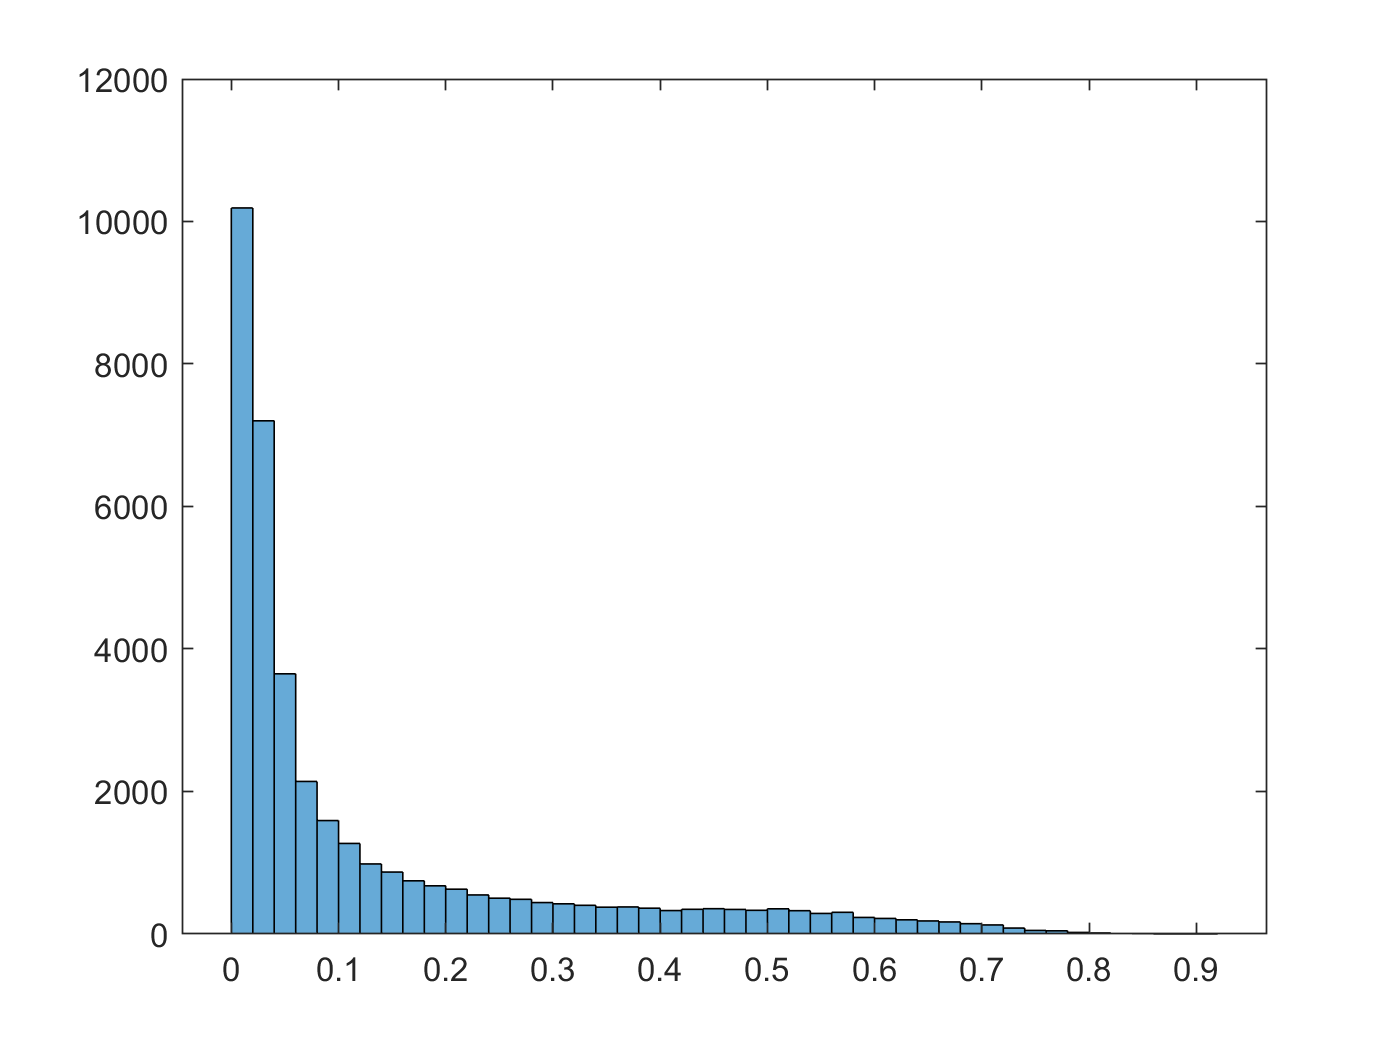

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 0.3682

y_diff = horzcat(y,(y-yfit))

y_diff =     1.0479   -0.0067
    1.0478   -0.0074
    1.0477   -0.0057
    1.0476   -0.0065
    1.0475   -0.0070
    1.0474   -0.0072
    1.0473   -0.0069
    1.0472   -0.0075
    1.0471   -0.0067
    1.0470   -0.0066


y_diff_percentage = abs(y-yfit)./y.*100

y_diff_percentage =     0.6364
    0.7087
    0.5439
    0.6171
    0.6653
    0.6892
    0.6592
    0.7145
    0.6383
    0.6288


length(y_diff_percentage)

ans = 38367

y_diff_percentage_avg = sum(y_diff_percentage)/length(y_diff_percentage)

y_diff_percentage_avg = 0.8437


(Y_test_SOH - yfit_test) 

ans =     0.0070
    0.0060
    0.0054
    0.0064
    0.0069
    0.0060
    0.0061
    0.0055
    0.0059
    0.0051


RMSE_test = sqrt(mean((Y_test_SOH - yfit_test).^2))

RMSE_test = 0.0120

y_diff_test = horzcat(Y_test_SOH,(Y_test_SOH-yfit_test))

y_diff_test =     1.0477    0.0070
    1.0476    0.0060
    1.0474    0.0054
    1.0473    0.0064
    1.0471    0.0069
    1.0470    0.0060
    1.0468    0.0061
    1.0467    0.0055
    1.0465    0.0059
    1.0464    0.0051


y_diff_test_percentage = abs(Y_test_SOH-yfit_test)./Y_test_SOH.*100

y_diff_test_percentage =     0.6653
    0.5683
    0.5191
    0.6108
    0.6591
    0.5721
    0.5798
    0.5223
    0.5634
    0.4883


y_diff_test_percentage_avg = sum(y_diff_test_percentage)/length(y_diff_test_percentage)

y_diff_test_percentage_avg = 0.9763

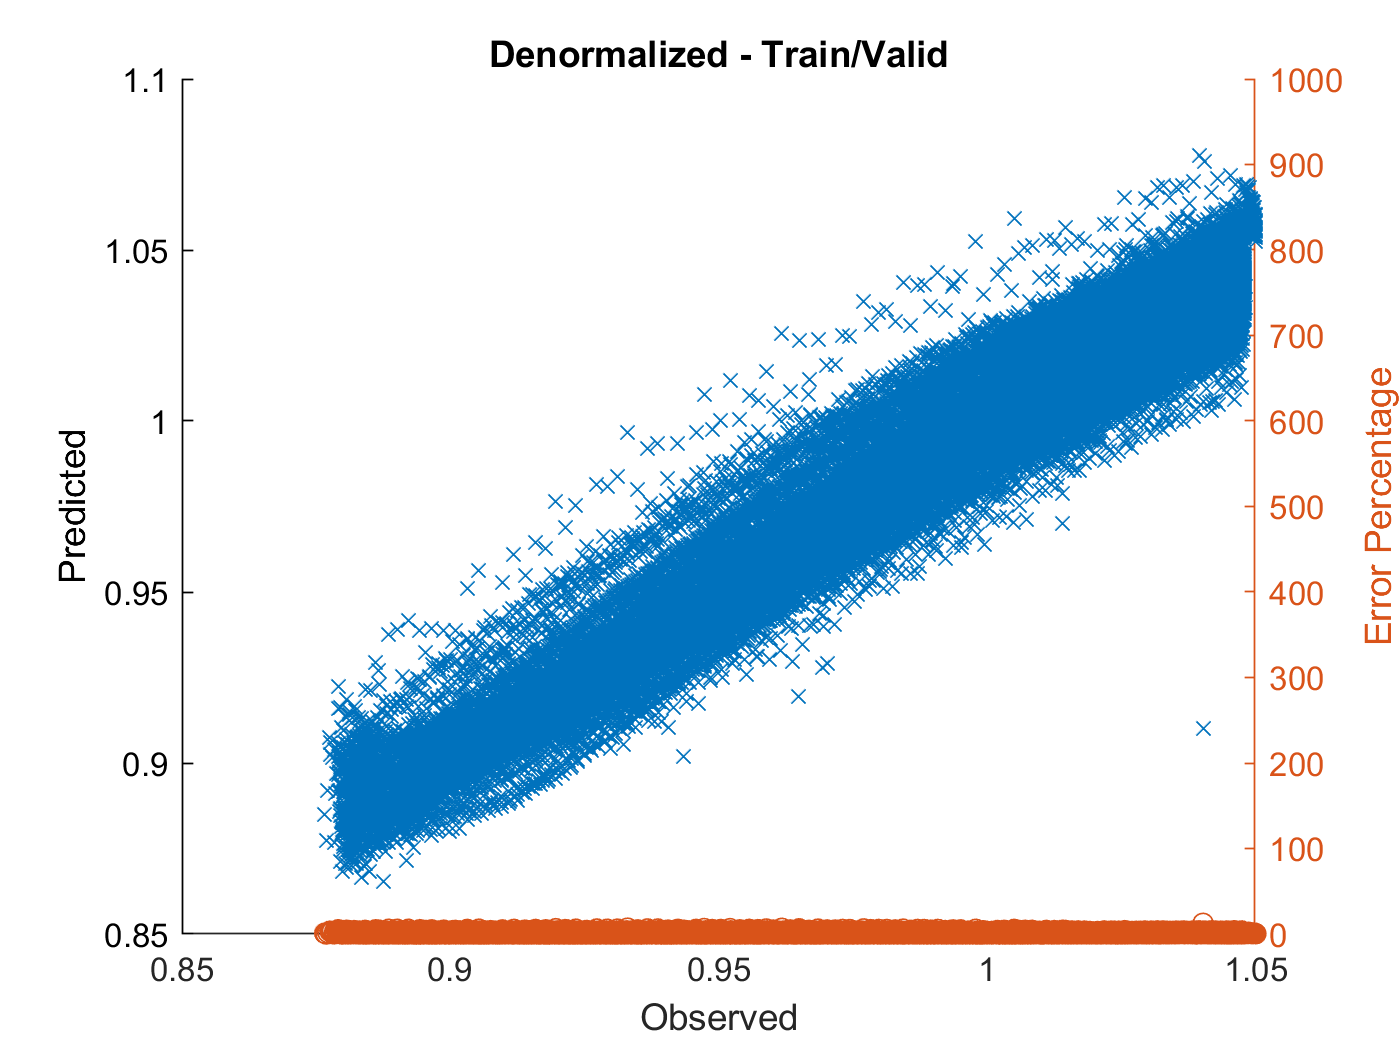

%{
result_firstCC_RUL_linear = table(num',y_trainValid,(y_trainValid-yfit_trainValid),y_trainValid_diff_percentage);
result_firstCC_RUL_linear.Properties.VariableNames = {'bat num','RUL','오차','오차비율'};
result_firstCC_RUL_linear
result_firstCC_RUL_linear_summary = table(RMSE_test,y_trainValid_diff_percentage_avg);
result_firstCC_RUL_linear_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_firstCC_RUL_linear_summary 
%}

figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(y,y_diff_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Train/Valid'

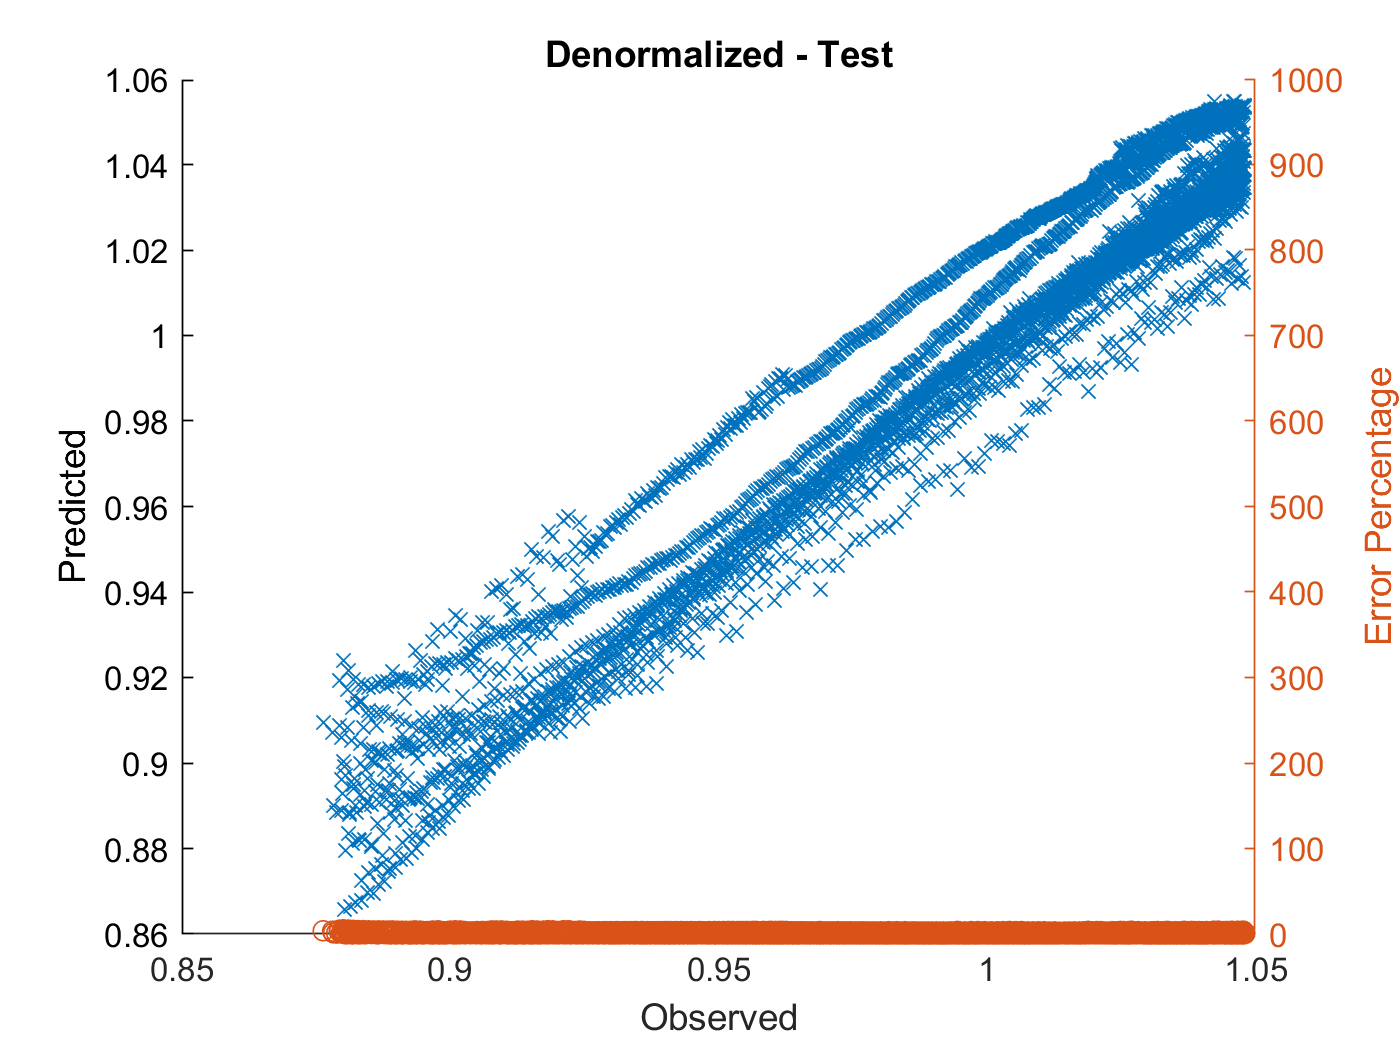


figure
hold on
plot(Y_test_SOH,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")

yyaxis right
ylabel('Error Percentage')
plot(Y_test_SOH,y_diff_test_percentage,'o');
ylim([0 1000])

hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;

# FNN 모델 생성

- FNN1 - 1 layer

if generate_model
netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_3 = train(netFNN1_3, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc


netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = idxTrainAll;
netFNN2_1.divideParam.valInd = idxValidAll;
netFNN2_1.divideParam.testInd = idxTestAll; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = idxTrainAll;
netFNN2_2.divideParam.valInd = idxValidAll;
netFNN2_2.divideParam.testInd = idxTestAll; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = idxTrainAll;
netFNN3_1.divideParam.valInd = idxValidAll;
netFNN3_1.divideParam.testInd = idxTestAll; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = idxTrainAll;
netFNN4_1.divideParam.valInd = idxValidAll;
netFNN4_1.divideParam.testInd = idxTestAll; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = idxTrainAll;
netFNN5_1.divideParam.valInd = idxValidAll;
netFNN5_1.divideParam.testInd = idxTestAll; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm_Vd_SOH', ynorm_SOH', 'useparallel',  'yes');
toc
%view(netFNN3_1)


save('ryan3_model_Vd_SOH.mat','netFNN1_1' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN1_2' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN1_3' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN2_1' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN2_2' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN3_1' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN4_1' ,'-append')
save('ryan3_model_Vd_SOH.mat','netFNN5_1' ,'-append')

end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.450614 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 1.967723 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 55.826575 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 7.672824 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 4.929666 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 67.917092 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 101.232141 seconds.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Elapsed time is 485.158162 seconds.


# FNN 예측


pFNN1_1 = netFNN1_1(xnorm_Vd_SOH(idxTestAll, :)');
pFNN1_2 = netFNN1_2(xnorm_Vd_SOH(idxTestAll, :)');
pFNN1_3 = netFNN1_3(xnorm_Vd_SOH(idxTestAll, :)');
pFNN2_1 = netFNN2_1(xnorm_Vd_SOH(idxTestAll, :)');
pFNN2_2 = netFNN2_2(xnorm_Vd_SOH(idxTestAll, :)');
pFNN3_1 = netFNN3_1(xnorm_Vd_SOH(idxTestAll, :)');
pFNN4_1 = netFNN4_1(xnorm_Vd_SOH(idxTestAll, :)');
pFNN5_1 = netFNN5_1(xnorm_Vd_SOH(idxTestAll, :)');

ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pFNN1_1_hat = pFNN1_1 * yrate_SOH + ymin_SOH;
pFNN1_2_hat = pFNN1_2 * yrate_SOH + ymin_SOH;
pFNN1_3_hat = pFNN1_3 * yrate_SOH + ymin_SOH;
pFNN2_1_hat = pFNN2_1 * yrate_SOH + ymin_SOH;
pFNN2_2_hat = pFNN2_2 * yrate_SOH + ymin_SOH;
pFNN3_1_hat = pFNN3_1 * yrate_SOH + ymin_SOH;
pFNN4_1_hat = pFNN4_1 * yrate_SOH + ymin_SOH;
pFNN5_1_hat = pFNN5_1 * yrate_SOH + ymin_SOH;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 0.0107

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 0.0112

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 0.0075

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 0.0116

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 0.0100

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 0.0105

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 0.0101

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 0.0091



y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_SOH'-pFNN1_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_1_hat_avg = 0.8386

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_2_hat_avg = 0.8574

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_SOH'-pFNN1_3_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN1_3_hat)./Y_test_SOH')

y_test_diff_percentage_FNN1_3_hat_avg = 0.5755

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_SOH'-pFNN2_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN2_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN2_1_hat_avg = 0.9113

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_SOH'-pFNN2_2_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN2_2_hat)./Y_test_SOH')

y_test_diff_percentage_FNN2_2_hat_avg = 0.7731

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_SOH'-pFNN3_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN3_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN3_1_hat_avg = 0.8032

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_SOH'-pFNN4_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN4_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN4_1_hat_avg = 0.7864

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_SOH'-pFNN5_1_hat)./Y_test_SOH'.*100)/length(abs(Y_test_SOH'-pFNN5_1_hat)./Y_test_SOH')

y_test_diff_percentage_FNN5_1_hat_avg = 0.7051

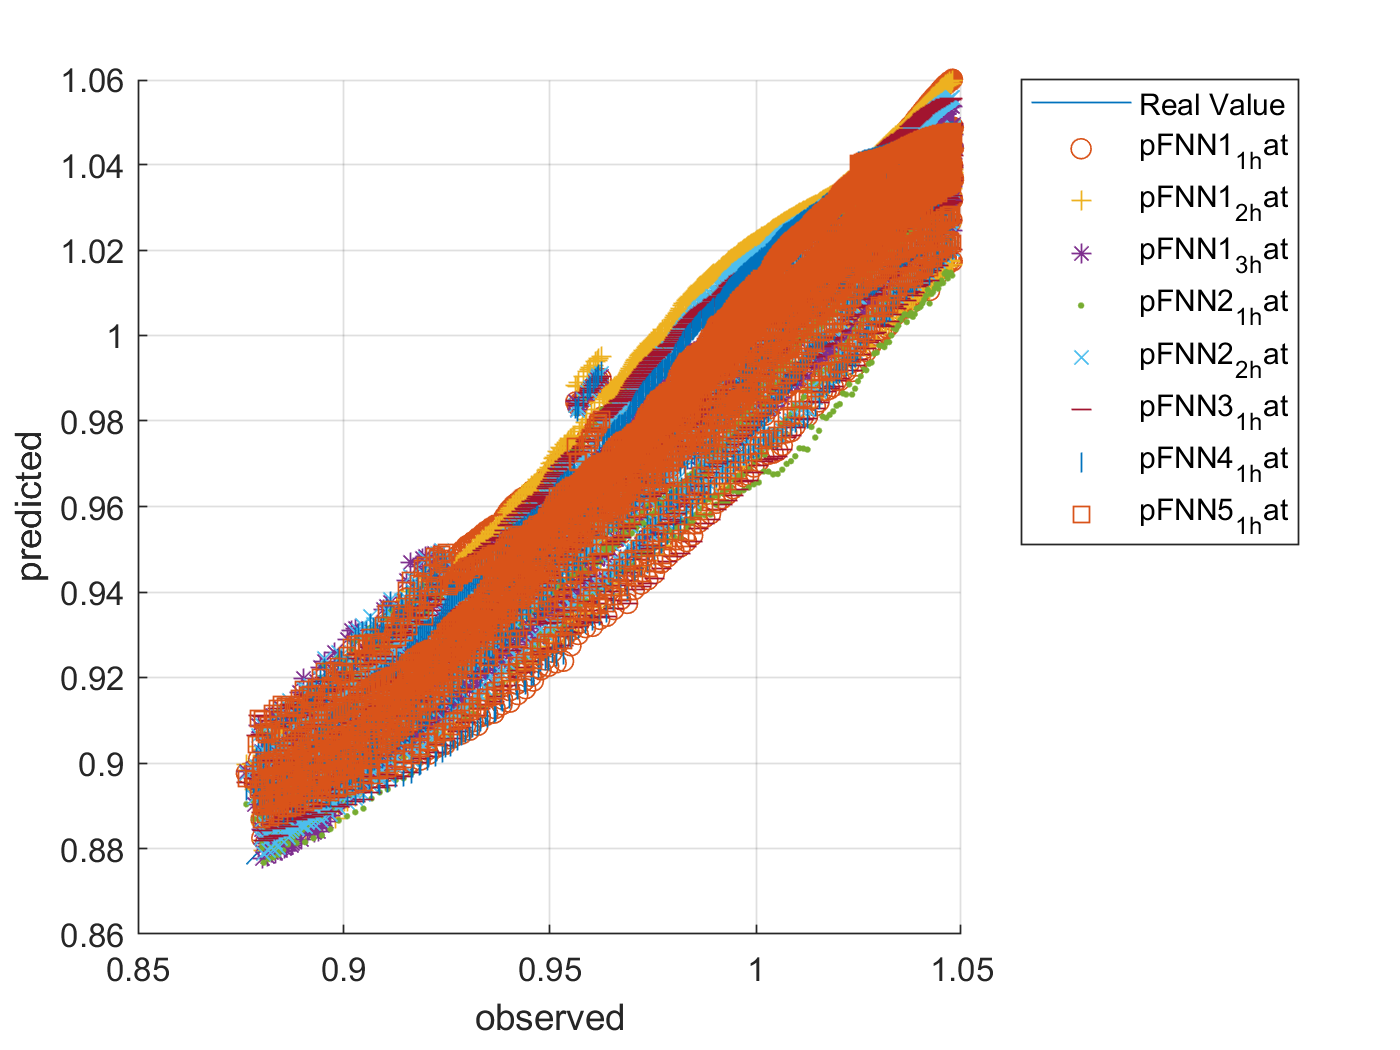



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')


y_test_diff_percentage_FNN1_2_hat = abs(Y_test_SOH'-pFNN1_2_hat)./Y_test_SOH'.*100

y_test_diff_percentage_FNN1_2_hat =     0.8677    0.8733    0.8500    0.8679    0.8770    0.8556    0.8390    0.8124    0.8174    0.8042    0.7883    0.8035    0.8015    0.7763    0.7549    0.7898    0.7644    0.7658    0.7558    0.7462    0.7087    0.7104    0.6589    0.6611    0.6215    0.6364    0.6366    0.6304    0.6246    0.6415    0.7125    0.6244    0.6150    0.6215    0.6460    0.6494    0.6106    0.6285    0.6165    0.6008    0.6039    0.5952    0.5766    0.5751    0.5647    0.5477    0.5571    0.5463    0.5147    0.4813


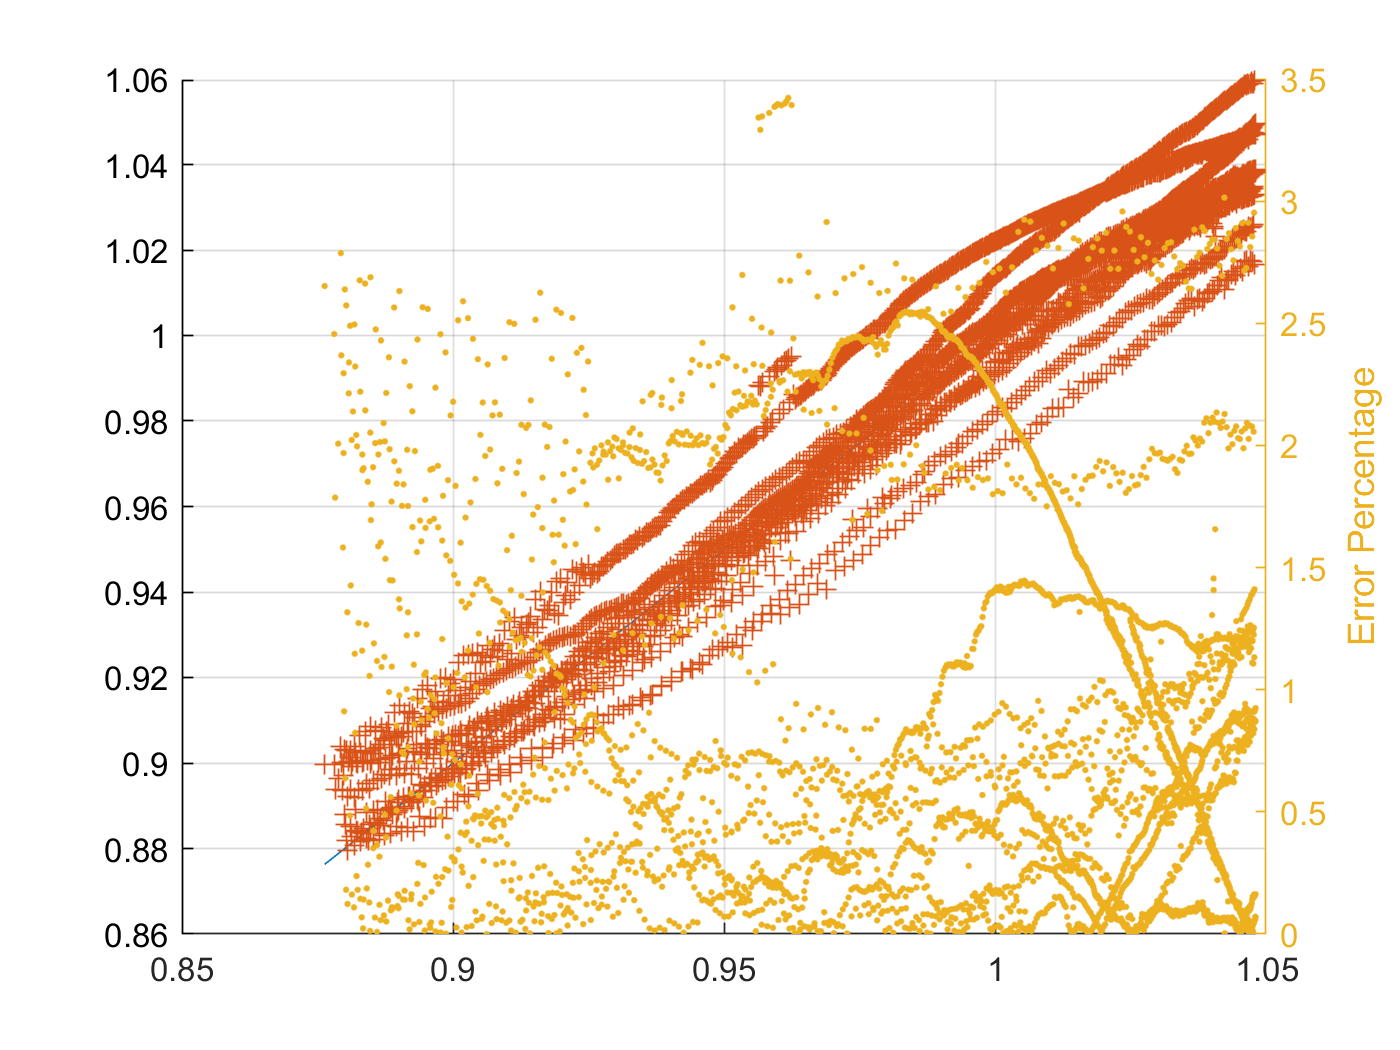

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_2_hat,'+')

yyaxis right
ylabel('Error Percentage')
plot(ytest,y_test_diff_percentage_FNN1_2_hat,'.')

hold off

pFNN1_1_self = netFNN1_1(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN1_2_self = netFNN1_2(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN1_3_self = netFNN1_3(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN2_1_self = netFNN2_1(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN2_2_self = netFNN2_2(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN3_1_self = netFNN3_1(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN4_1_self = netFNN4_1(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');
pFNN5_1_self = netFNN5_1(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)');

ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pFNN1_1_self_hat = pFNN1_1_self * yrate_SOH + ymin_SOH;
pFNN1_2_self_hat = pFNN1_2_self * yrate_SOH + ymin_SOH;
pFNN1_3_self_hat = pFNN1_3_self * yrate_SOH + ymin_SOH;
pFNN2_1_self_hat = pFNN2_1_self * yrate_SOH + ymin_SOH;
pFNN2_2_self_hat = pFNN2_2_self * yrate_SOH + ymin_SOH;
pFNN3_1_self_hat = pFNN3_1_self * yrate_SOH + ymin_SOH;
pFNN4_1_self_hat = pFNN4_1_self * yrate_SOH + ymin_SOH;
pFNN5_1_self_hat = pFNN5_1_self * yrate_SOH + ymin_SOH;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 0.0115

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 0.0113

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 0.0085

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 0.0119

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 0.0105

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 0.0113

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 0.0109

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 0.0103

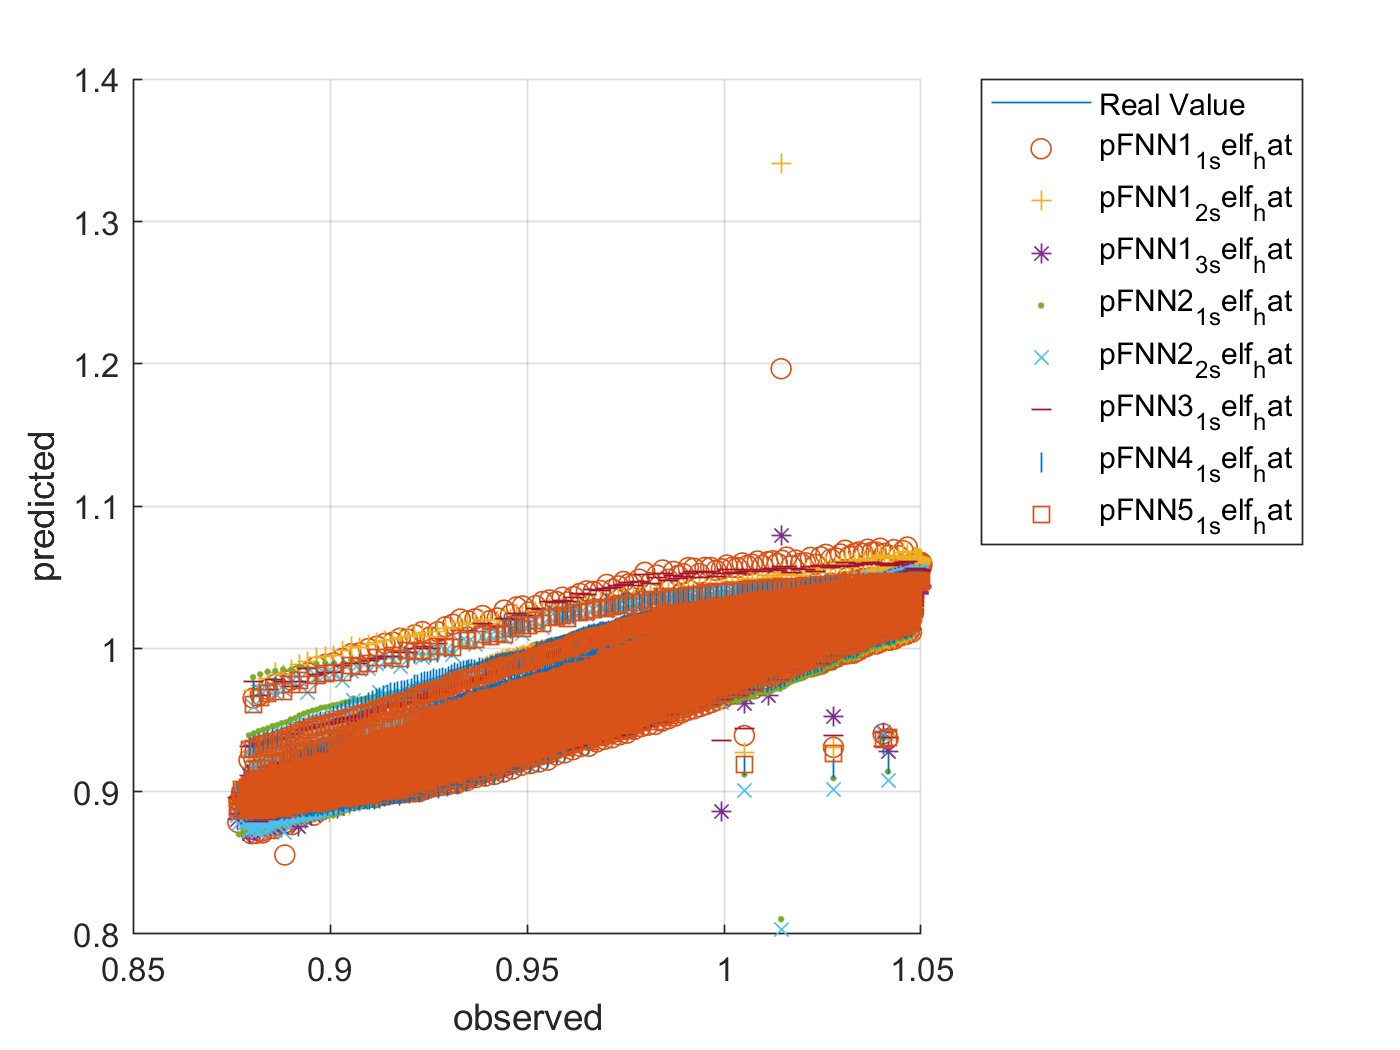



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;


- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.


if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_Vd_SOH', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_SOH);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(idxTrainAll, :);
valtbl = tbl(idxValidAll, :);
testtbl = tbl(idxTestAll, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);
toc




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.80 |         0.70 |       0.3176 |       0.2472 |          0.0010 |
|       1 |          50 |       00:00:08 |         0.12 |         0.12 |       0.0076 |       0.0075 |          0.0010 |
|       1 |         100 |       00:00:11 |         0.11 |         0.09 |       0.0057 |       0.0040 |          0.0010 |
|       1 |         150 |       00:00:13 |         0.09 |         0.09 |       0.0043 |   

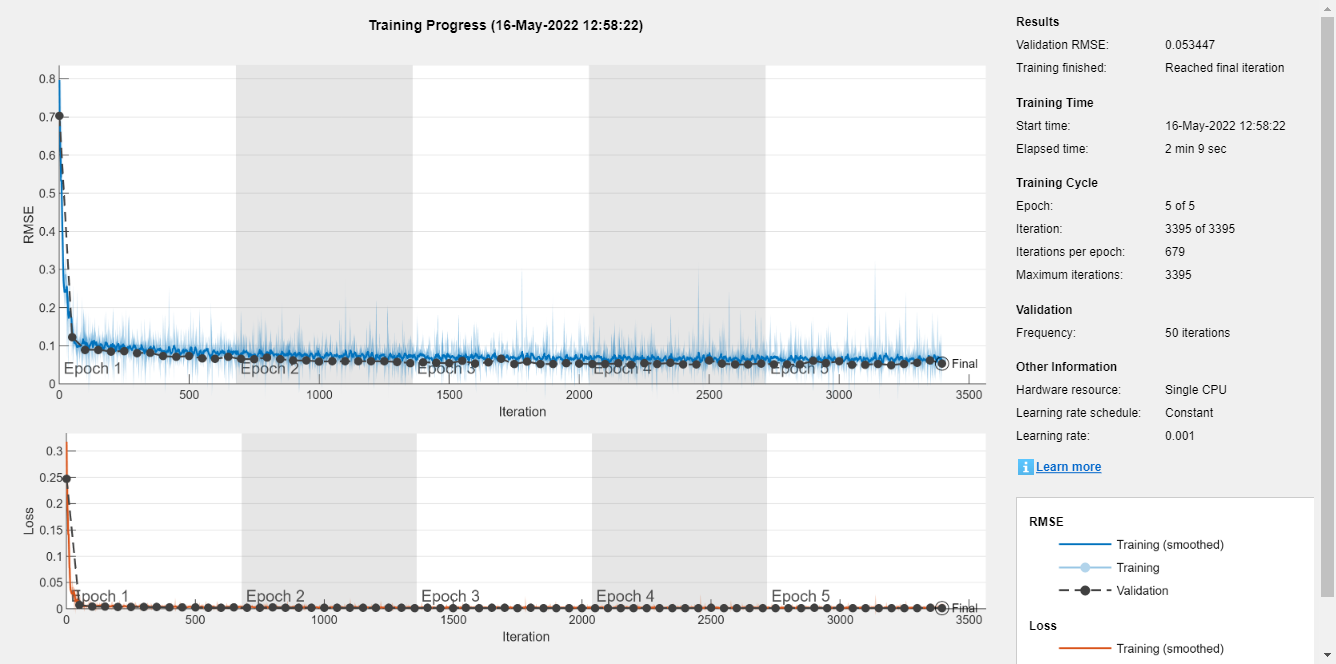

Elapsed time is 149.820629 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         0.79 |         0.77 |       0.3137 |       0.2927 |          0.0010 |
|       1 |          50 |       00:00:10 |         0.13 |         0.12 |       0.0088 |       0.0067 |          0.0010 |
|       1 |         100 |       00:00:12 |         0.10 |         0.09 |       0.0049 |       0.0044 |          0.0010 |
|       1 |         150 |       00:00:17 |         0.08 |         0.10 |       0.0036 |   

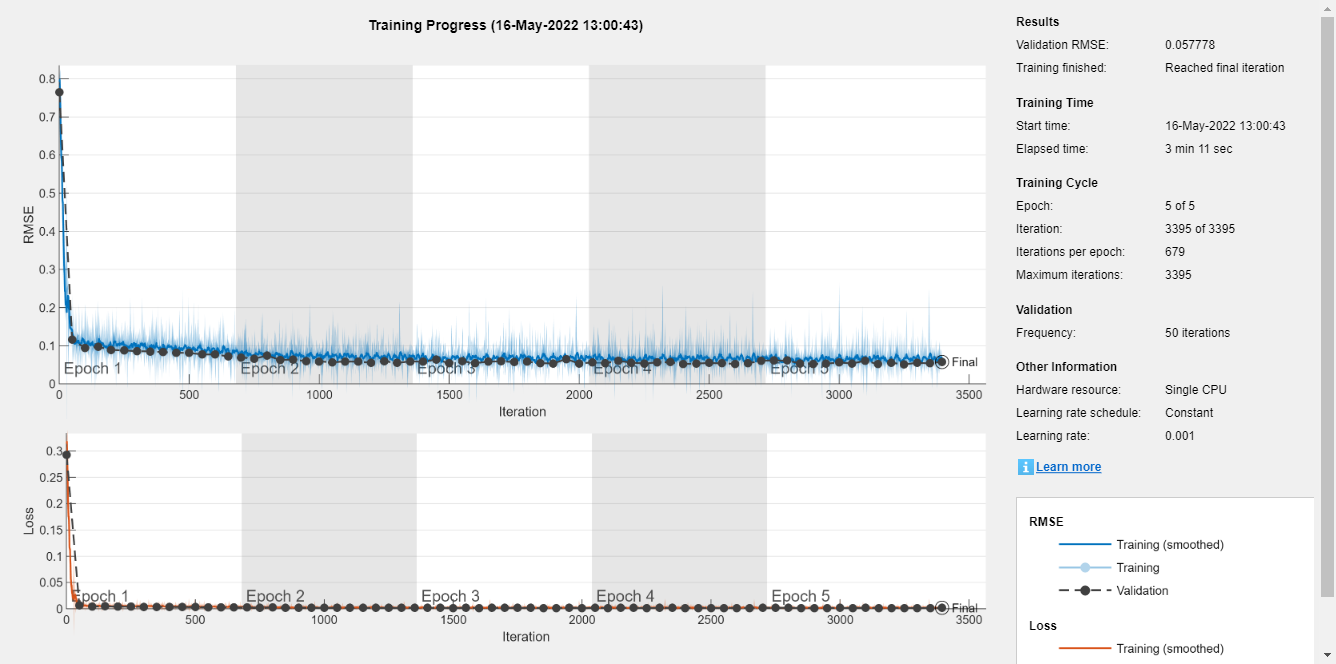

Elapsed time is 202.641618 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.81 |         0.78 |       0.3275 |       0.3034 |          0.0010 |
|       1 |          50 |       00:00:12 |         0.19 |         0.19 |       0.0188 |       0.0182 |          0.0010 |
|       1 |         100 |       00:00:13 |         0.12 |         0.10 |       0.0077 |       0.0049 |          0.0010 |
|       1 |         150 |       00:00:14 |         0.10 |         0.09 |       0.0054 |   

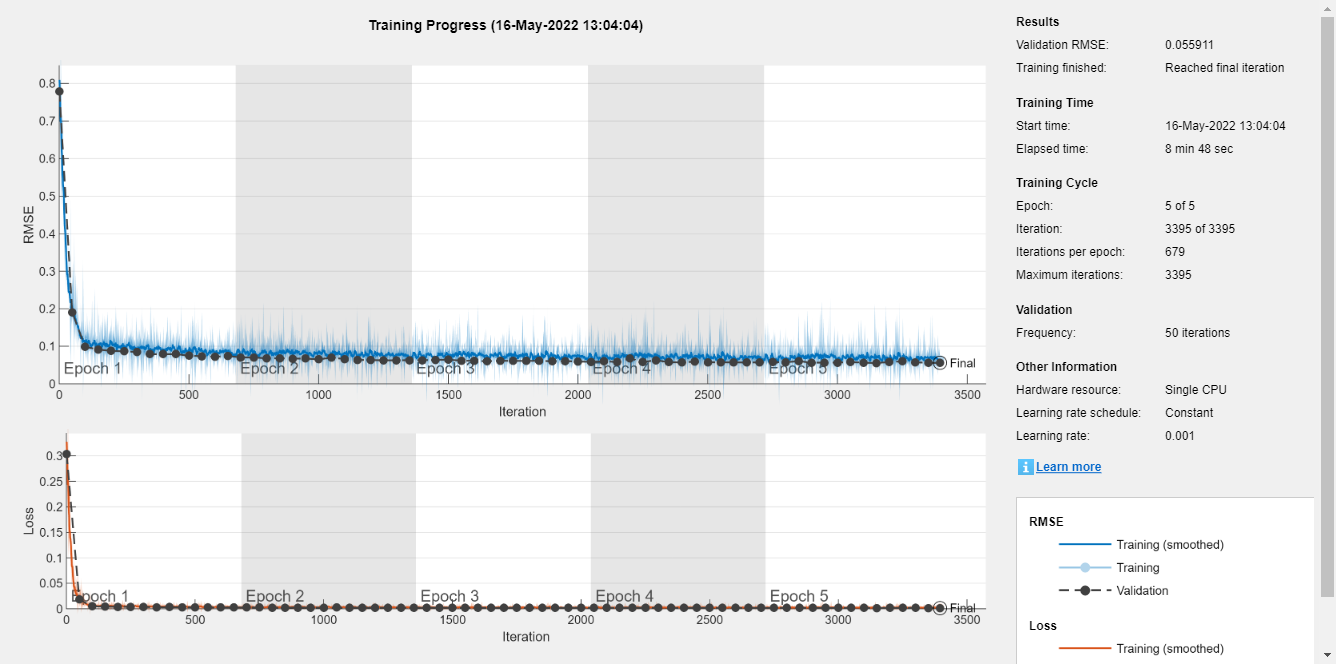

Elapsed time is 542.773905 seconds.


layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);
toc

layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);
toc

%%%% 시간이 오래 걸린다. 
%{
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);
toc

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);
toc


figure
plot(xnorm_Vd_SOH')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_Vd_SOH,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")
%}
%%%%%%%%%%%%%%

save('ryan3_model_Vd_SOH.mat','netCNN2_1' ,'-append')
save('ryan3_model_Vd_SOH.mat','netCNN2_2' ,'-append')
%save('ryan3_model_Vd_SOH.mat','netCNN2_3' ,'-append')
%save('ryan3_model_Vd_SOH.mat','netCNN2_4' ,'-append')
save('ryan3_model_Vd_SOH.mat','netCNN1_1' ,'-append')

end


cellx = num2cell(xnorm_Vd_SOH(idxTestAll, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);



ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pCNN2_1_hat = pCNN2_1 * yrate_SOH + ymin_SOH;
pCNN2_2_hat = pCNN2_2 * yrate_SOH + ymin_SOH;
%pCNN2_3_hat = pCNN2_3 * yrate_SOH + ymin_SOH;
%pCNN2_4_hat = pCNN2_4 * yrate_SOH + ymin_SOH;
pCNN1_1_hat = pCNN1_1 * yrate_SOH + ymin_SOH;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_1_hat = single
0.0106

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_hat = single
0.0110

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN1_1_hat = single
0.0116

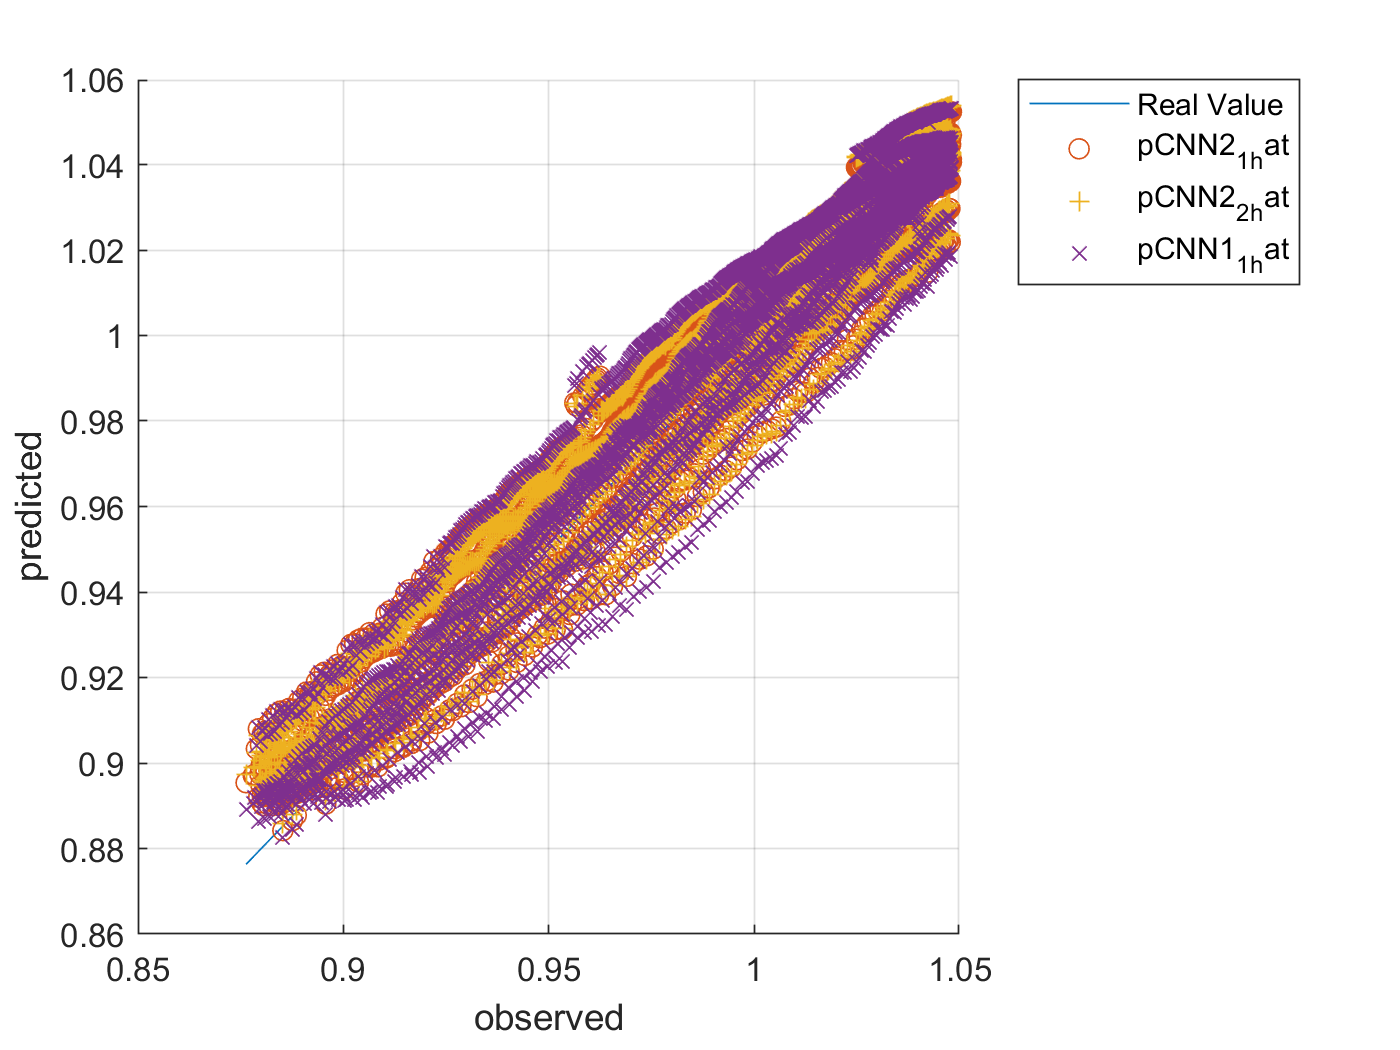




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')






cellx_self = num2cell(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pCNN2_1_self_hat = pCNN2_1_self * yrate_SOH + ymin_SOH;
pCNN2_2_self_hat = pCNN2_2_self * yrate_SOH + ymin_SOH;
%pCNN2_3_self_hat = pCNN2_3_self * yrate_SOH + ymin_SOH;
%pCNN2_4_self_hat = pCNN2_4_self * yrate_SOH + ymin_SOH;
pCNN1_1_self_hat = pCNN1_1_self * yrate_SOH + ymin_SOH;


rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
0.0111

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
0.0114

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
0.0116

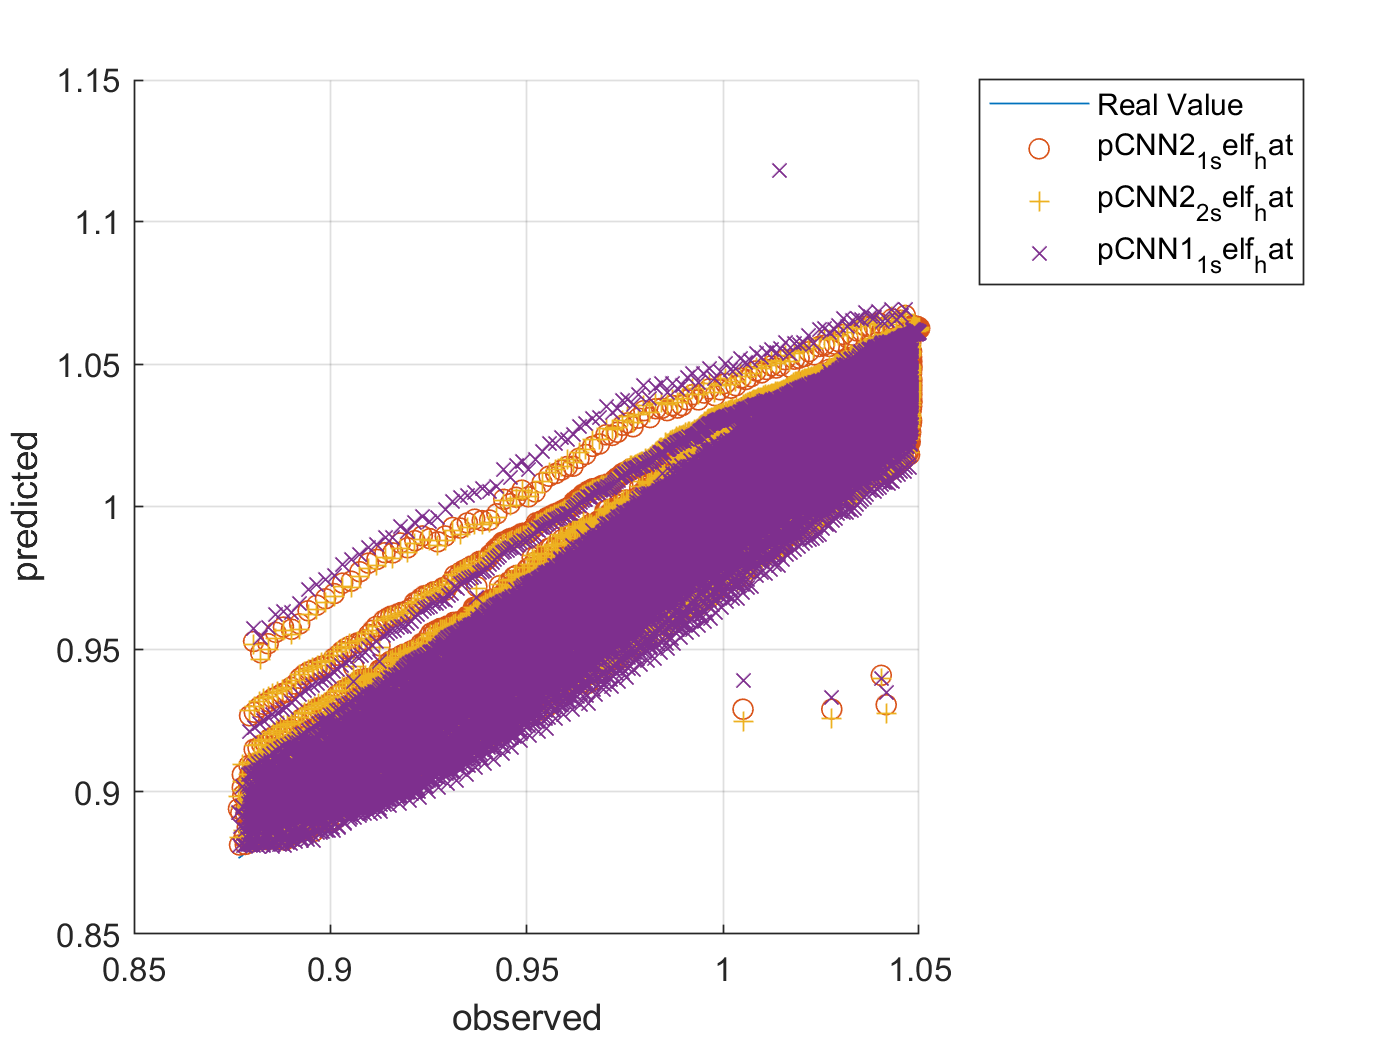




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

cc_input_size = 20;
numHiddenUnits = 50;

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         0.62 |         0.60 |       0.1944 |       0.1833 |          0.0010 |
|       1 |          50 |       00:00:18 |         0.18 |         0.20 |       0.0167 |       0.0193 |          0.0010 |
|       1 |         100 |       00:00:26 |         0.16 |         0.15 |       0.0126 |       0.0114 |          0.0010 |
|       1 |         150 |       00:00:32 |         0.11 |         0.11 |       0.0062 |       0.0062 |          0.0010 |
|       

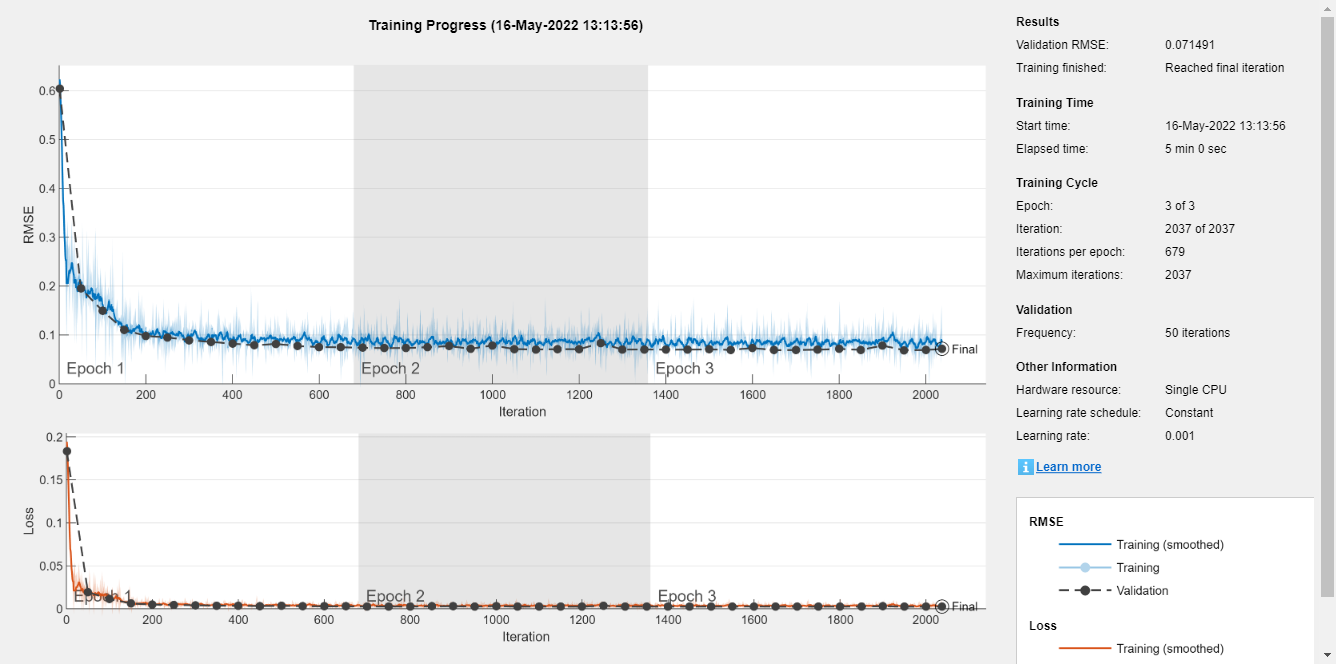

Elapsed time is 317.123121 seconds.


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.73 |         0.71 |       0.2675 |       0.2510 |          0.0010 |
|       1 |          50 |       00:00:21 |         0.27 |         0.22 |       0.0351 |       0.0236 |          0.0010 |
|       1 |         100 |       00:00:29 |         0.18 |         0.15 |       0.0164 |       0.0112 |          0.0010 |
|       1 |         150 |       00:00:39 |         0.12 |         0.10 |       0.0068 |       0.0051 |          0.0010 |
|       

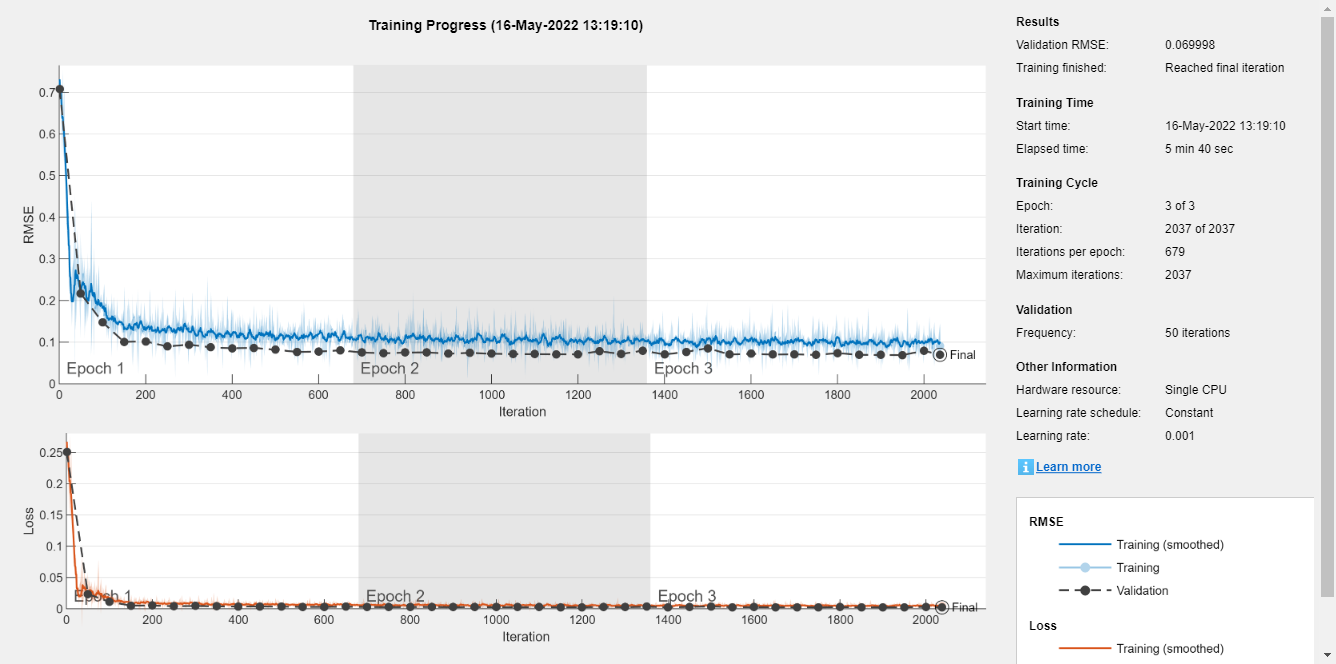

Elapsed time is 357.003925 seconds.



if generate_model
layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_Vd_SOH', 1)';
cellyB = num2cell(ynorm_SOH);

traincellx = cellx(idxTrainAll, :);
valcellx = cellx(idxValidAll, :);
testcellx = cellx(idxTestAll, :);

traincellyB = cellyB(idxTrainAll, :);
valcellyB = cellyB(idxValidAll, :);
testcellyB = cellyB(idxTestAll, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count_lstm, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);
toc 

tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);
toc

save('ryan3_model_Vd_SOH.mat','netLSTM' ,'-append')
save('ryan3_model_Vd_SOH.mat','netLSTM2' ,'-append')

end


pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm_Vd_SOH(idxTestAll, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_Vd_SOH(idxTestAll, :)', 1)));
ytest = ynorm_SOH(idxTestAll, :)*yrate_SOH + ymin_SOH;
pLSTM_hat = pLSTM * yrate_SOH + ymin_SOH;
pLSTM2_hat = pLSTM2 * yrate_SOH + ymin_SOH;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
0.0160

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
0.0160

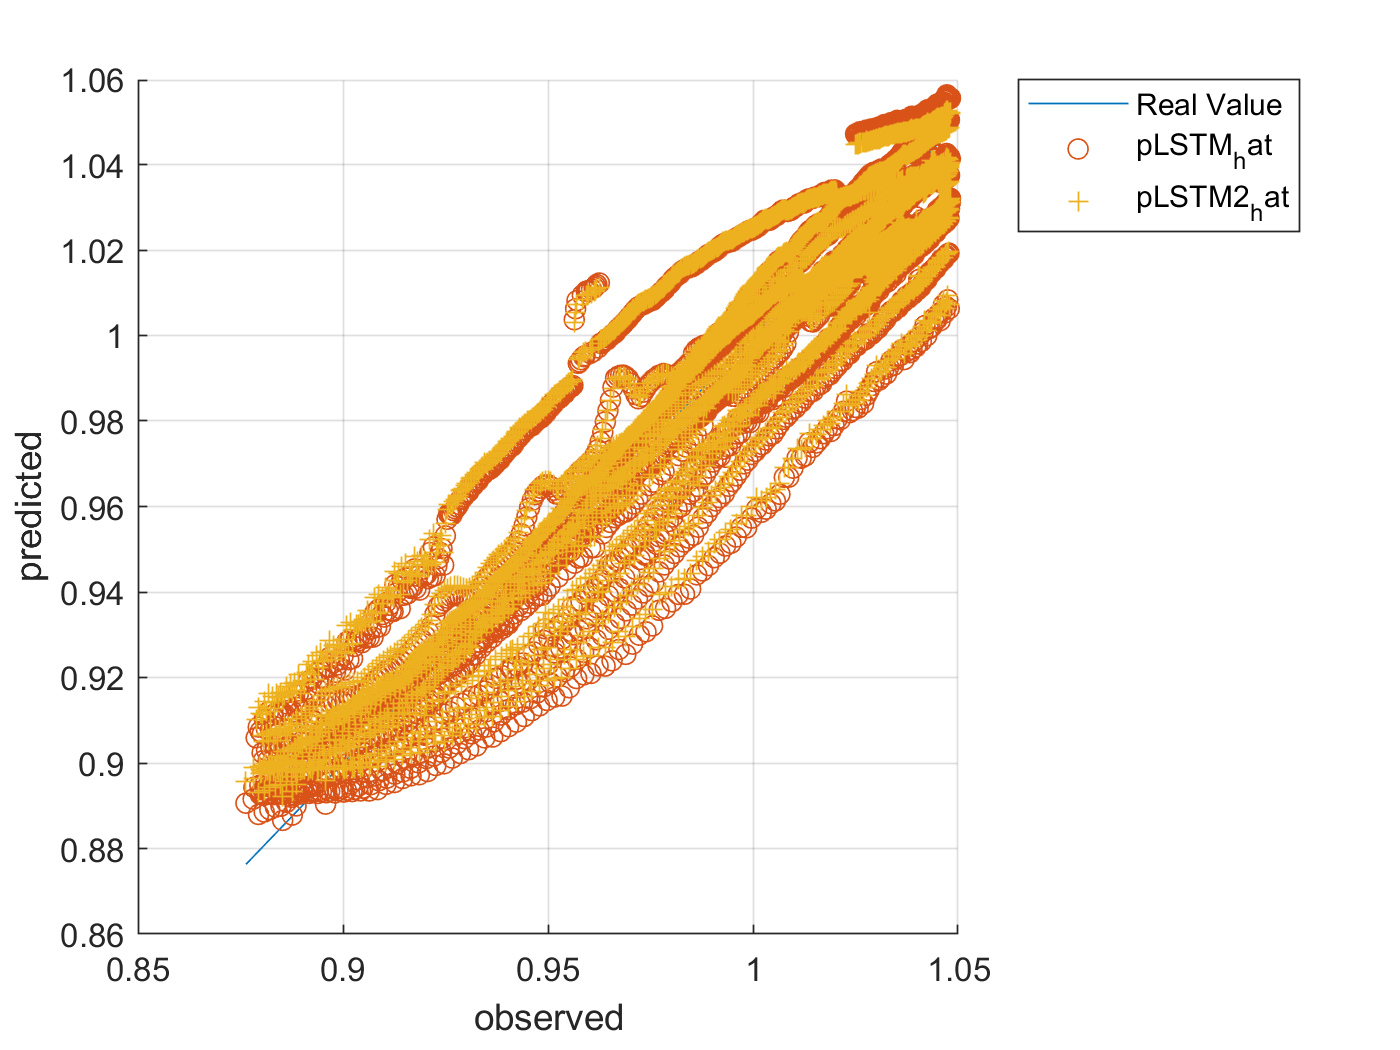



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_Vd_SOH([idxTrainAll idxValidAll], :)', 1)));
ytrain_self = ynorm_SOH([idxTrainAll idxValidAll], :)*yrate_SOH + ymin_SOH;
pLSTM_self = pLSTM_self * yrate_SOH + ymin_SOH;
pLSTM2_self = pLSTM2_self * yrate_SOH + ymin_SOH;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
0.0144

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
0.0142

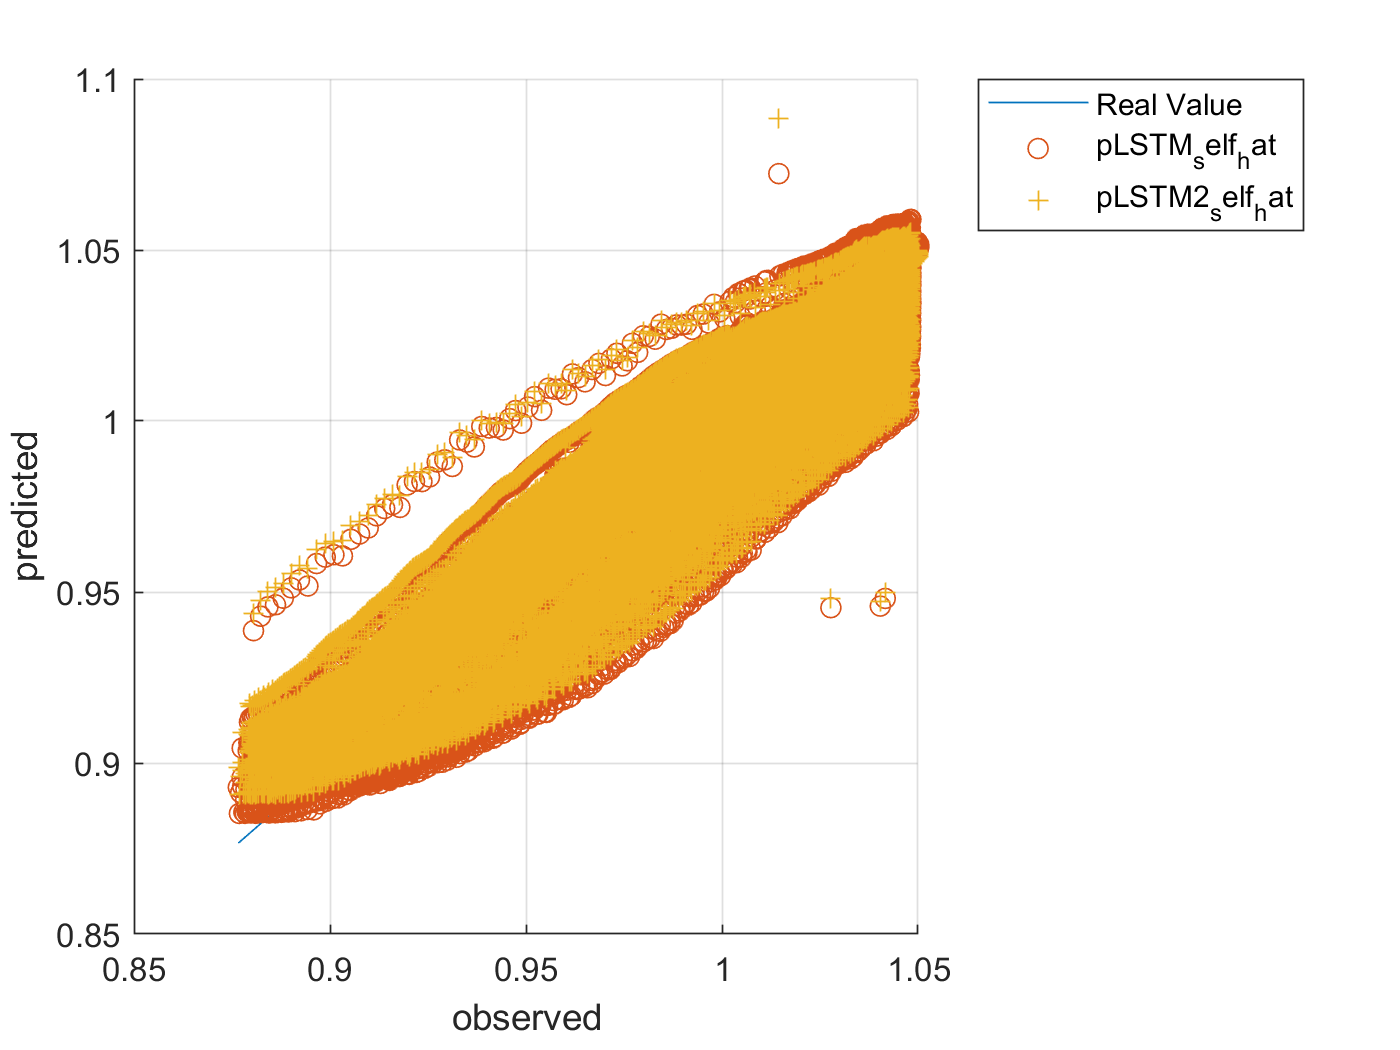


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')